# Homework 2

Kathryn Atherton

ABE 30100

February 15, 2019

Intracellular biochemical reactions can be complicated.  Assume adenosine triphosphate (ATP) is created and consumed within a cell at different rates by different reactions (see reaction rates below).  

If the cell is at steady state, what is the ATP concentration in the cell?  

Rates of reaction   

r1(CATP) = + k1*CATP         r2(CATP) = - Vm*CATP/(Km+ CATP)              r3(CATP)= -k3* CATP^2           

Value of reaction rate constants  

k1=7/min    Vm=0.1 mol/L-min     Km=1 mol/L       k3= 0.02 L/mol-min  

## Part A:        

(2 points) Provide an appropriate plot of the overall rate of ATP reaction vs. ATP concentration

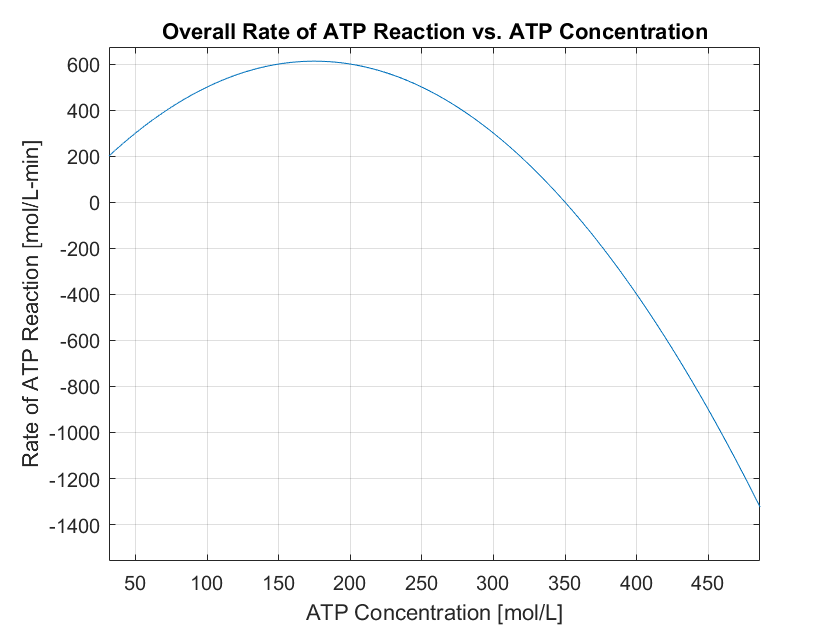

k1 = 7; % [min^-1]
vm = 0.1; % [mol/L-min]
km = 1; % [mol/L]
k3 = 0.02; % [L/mol-min]

syms Catp % [mol/L]
r1 = k1 * Catp; % [mol/L-min]
r2 = - (vm * Catp) / (km + Catp); % [mol/L-min]
r3 = -k3 * Catp ^ 2; % [mol/L-min]

roverall = r1 + r2 + r3;
ezplot(roverall, [0,500])
set(gca,'XGrid','on','YGrid','on')
title('Overall Rate of ATP Reaction vs. ATP Concentration')
ylabel('Rate of ATP Reaction [mol/L-min]')
xlabel('ATP Concentration [mol/L]')

## Part B:

(9 points) Please write computer programs using 3 different root finding methods and use each to calculate the steady state ATP concentration (CATP, mol/L) within an error limit of 0.0001 mol/L.  (Note: you do not need to provide program code)

- Bisection method  (use starting points 200 and 400)

- False position method (use starting points 200 and 400)

- Newton-Raphson method(starting point 300)

error_tol = 0.0001;

x1 = 200; % for bisection and regula falsi
y1 = double(subs(roverall,Catp,x1)); % for bisection and regula falsi
x2 = 400; % for bisection and regula falsi
y2 = double(subs(roverall,Catp,x2)); % for bisection and regula falsi
x3 = 300; % for Newton-Raphson

colNames = {'Iteration', 'Catp', 'rCatp'};
bisection_method = bisection(roverall, x1, y1, x2, y2, error_tol);
Table_bisection = array2table(bisection_method, 'VariableNames', colNames)

Table_bisection = 22×3 table
    Iteration     Catp       rCatp  
    _________    ______    _________

        1           300        299.9
        2           350    -0.099715
        3           325        162.4
        4         337.5       84.275
        5        343.75       42.869
        6        346.88        21.58
        7        348.44       10.789
        8        349.22       5.3568
        9        349.61       2.6316
       10         349.8       1.2667
       11         349.9      0.58369
       12        349.95      0.24203
       13        349.98     0.071171
       14        349.99    -0.014269
       15        349.98     0.028452
       16        349.98    0.0070918


false_position_method = regula_falsi(roverall, x1, y1, x2, y2, error_tol);
Table_false_position = array2table(false_position_method, 'VariableNames', colNames)

Table_false_position = 22×3 table
    Iteration     Catp       rCatp   
    _________    ______    __________

        1        319.98        192.02
        2        367.98       -132.46
        3        348.78        8.4267
        4         360.3       -74.318
        5        355.69       -40.575
        6        352.92        -20.74
        7        351.27       -8.9879
        8        350.27       -1.9906
        9        349.67         2.188
       10        350.03      -0.31706
       11        349.89       0.68584
       12        349.97      0.084299
       13        350.01      -0.15646
       14        349.99     -0.060125
       15        349.99    -0.0023392
       16        349.98      0.032326


newton_raphson_method = newton_raphson(roverall, x3, error_tol);
Table_newton_raphson = array2table(newton_raphson_method, 'VariableNames', colNames)

Table_newton_raphson = 4×3 table
    Iteration     Catp        rCatp   
    _________    ______    ___________

        1        359.98        -71.952
        2        350.26        -1.8912
        3        349.99     -0.0014557
        4        349.99    -8.6474e-10


For each method provide the following:

- A table showing the calculated values of the estimated root, CATP, the value of the rate, r(CATP), and the number of iterations needed to reach the final value.  

## Part C:

(4 points) Based on your results, explain the benefits and limitations of each method.

**Bisection Method benefits**

- guaranteed convergence on a root (as long as there is a root between the starting points)

- generally a uniform convergence upon the root

**Bisection Method limitations**

- slowest method of the three

**False Postition Method benefits**

- guaranteed convergence on a root (as long as there is a root between the starting points)

- theoretically faster than bisection method (although here it did not perform the algorithm in less iterations)

**False Position Method limitations**

- convergence upon the root is not uniform (i.e. estimated zero goes from -132 to 8 to -74)

**Newton Raphson Method benefits**

- fastest method of the three

- only requires one point

**Newton Raphson Method limitations**

- requires the derivative to be known (can be difficult if the function is very complex)

- convergence depends on slopes between the starting point and the zero (i.e. if there is a maximum or minimum that the method converges on, the method fails; if the method converges near a maximum or minimum, the method takes more iterations to converge on the zer

## Functions

function [matrix] = newton_raphson(f, x1, error_tol)
    % sets up the output matrix which will be formatted as a table later
    matrix = zeros(1,3);
    
    % sets zero to the value of the function at the given x point
    Catp = x1;
    zero = double(subs(f));
    
    % starts iteration counter 
    i = 1;   
    
    % checks to see if another iteration should be performed
    while abs(zero) > error_tol 
        % finds the slope of the function at the given point
        slope = double(subs(diff(f)));                         
        
        % checks for a minimum or maximum
        if slope == 0                                          
            fprintf('Error: stuck at minimum or maximum of function.\n')
            
            % breaks the while loop so that the function doesn't go on 
            % forever
            zero = 0;                                          
            Catp = 'N/A'; 
        else
            % finds the b of the function y = mx + b
            b = zero - slope * Catp;
            
            % finds the new x where y = 0 for the linear function
            Catp = double(-b / slope);   
            
            % finds the value of the function at the x found above
            zero = double(subs(f));
            
            % stores values in table to be output
            matrix(i, 1) = i;
            matrix(i, 2) = Catp;
            matrix(i, 3) = zero;
            
            % adds iteration to counter
            i = i + 1;
        end
    end
    
    % changes the zero value to N/A in the case that a maximum was found 
    % after loop break
    if Catp == 'N/A'                                           
        zero  = 'N/A';
    end
end